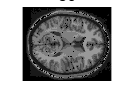

load Brain.mat

% Apply a Gaussian filter to reduce noise
filter_size = 5;
sigma = 1; % Standard deviation of the Gaussian kernel
filtered_slice = imgaussfilt(T1(:, :, 10), sigma, 'FilterSize', filter_size);
%filtered_slice = T1(:,:,10);

num_clusters = 7; % The number of clusters should be one more than the number of tissue layers to account for the background
[cluster_indices, cluster_centers] = kmeans(double(filtered_slice(:)), num_clusters);
thresholds = sort(cluster_centers);

% Initialize the masks
tissue_masks = false(362, 434, 6);

% Apply the thresholds to create binary masks
for i = 1:6
    tissue_masks(:, :, i) = filtered_slice > thresholds(i) & filtered_slice <= thresholds(i + 1);
end

min_pixel_count = 50; % Adjust this value according to your dataset

    for i = 1:6
        tissue_masks(:, :, i) = bwareaopen(tissue_masks(:, :, i), min_pixel_count);
    end

    labeled_image = zeros(362, 434);
    %show image one by one
    for i = 1:6
        labeled_image(tissue_masks(:, :, i)) = i * 0.1;
    end

    imshow(labeled_image);
    title(min_pixel_count);

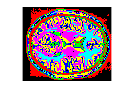



% Define a color map with 6 distinct colors, each row represents R, G, and B values (range: 0-1)
color_map = [
    1, 0, 0;      % Red
    0, 1, 0;      % Green
    0, 0, 1;      % Blue
    1, 1, 0;      % Yellow
    1, 0, 1;      % Magenta
    0, 1, 1       % Cyan
];

% Initialize an empty RGB image with the same dimensions as the labeled_image
rgb_image = zeros(size(labeled_image, 1), size(labeled_image, 2), 3);

% Assign colors to the tissue layers in the RGB image using the color map
for i = 1:6
    for j = 1:3
        rgb_image(:, :, j) = rgb_image(:, :, j) + (labeled_image == i * 0.1) * color_map(i, j);
    end
end

% Convert the RGB image to the uint8 data type
rgb_image = uint8(rgb_image * 255);

% Display the colored segmented image
imshow(rgb_image);